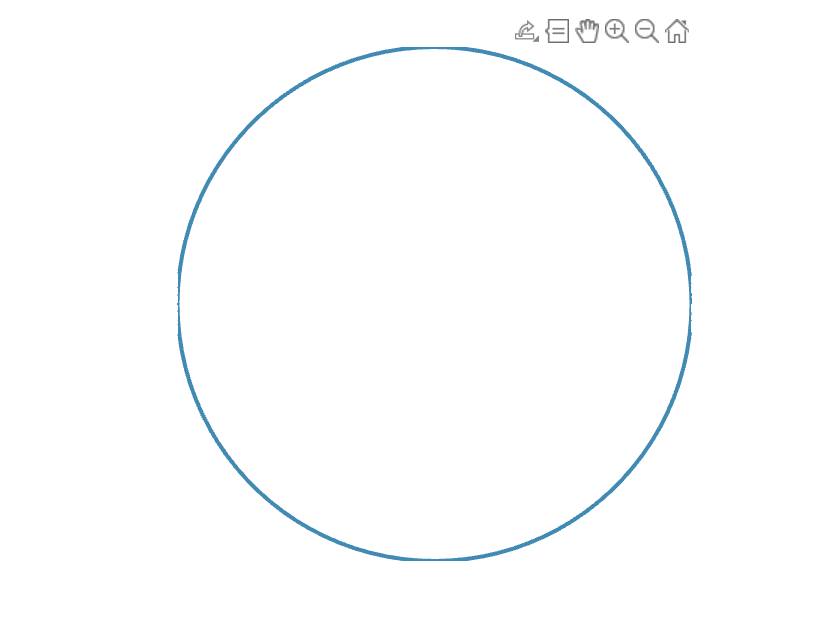

col = [65, 138, 179]/255;

dnum = 101;
t = linspace(0, 1, dnum);
x = cos(2*pi*t); y = sin(2*pi*t);

figure()
ax = gca;
plot(ax, x, y, '-', 'LineWidth', 2, 'Color', col);
set(ax, 'XTick', []); set(ax, 'YTick', []); set(ax, 'Visible', 'off'); box(ax, "off"); axis equal square;

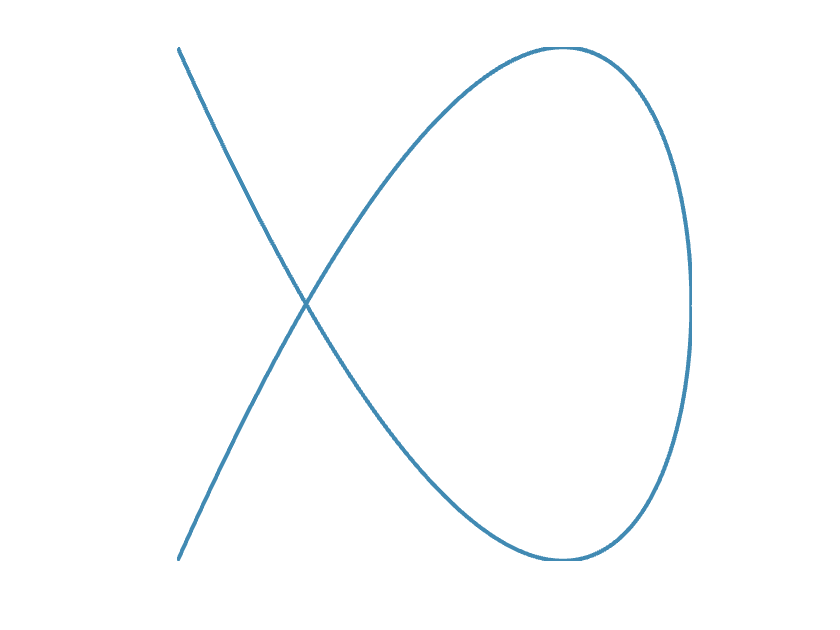


t = linspace(0, 2, 2*dnum);
x = cos(2*pi*t); y = sin(1.5*2*pi*t);

figure()
ax = gca;
plot(ax, x, y, '-', 'LineWidth', 2, 'Color', col);
set(ax, 'XTick', []); set(ax, 'YTick', []); set(ax, 'Visible', 'off'); box(ax, "off"); axis equal square;

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist('Data\case_1_kinematicMobility.mat', "file")
    load('Data\case_1_kinematicMobility.mat');
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end

randNumGen = @() pi*(2*rand([1, 2], "double") - 1) % between +pi and -pi

randNumGen = function_handle with value:
    @()pi*(2*rand([1,2],"double")-1)


r = randNumGen()

r =    -2.1513    2.9568


F_fxn = FRHLstance.F_fxn;

aa = 1; ll = 1; ank = pi/2; % some default vars
aInf = FRHLstance.aInf

aInf =    -2.3562   -2.3562


aSup = FRHLstance.aSup 

aSup =     0.7854    0.7854


Check if "aInf" is closer to "aSup" or "r" is closer to "aSup".

% arrange the points a certain way
pts = {aInf, r, aSup};
% iterate over each ordered pair and get the intervals of interest
inteval = cell(1, numel(pts)-1);
for i = 1:inteval
    % get a vector from point 1 (tail of arrow above) to point 2 (head)
    vec = pts{i+1} - pts{i+1}
    % ensure that this vector is not too small
    % ... for now I'm setting the threshold to 1% of the allowable
    % ... symmetric range that we have assumed
    % ... if the threshold is not cleared, use the next vector or the
    % ... previous vector
    if norm(vec) - 2*ank*1e-2 < 0
        switch i
            case 1
                vec = pts{i+2} - pts{i+1}
            case 2
                vec = pts{i} - pts{i-1}
        end
    end
    % get the phasor info
    phasorAngle1 = atan2(vec(2), vec(1))
    % get the x and y components for the line generator
    delX = cos(phasorAngle1)
    delY = sin(phasorAngle1)
    % find the a value at which the next point occurs
    aTemp = vec(1)./[delX, delY]; 
    aPtNext = aTemp(~isinf(aTemp));
    % current pt is at 0
    aPtCurr = 0;
    % find the intersection to pi-bounds (outer bounds)
    aPiX = (pi*[-1, 1] - repmat(pts{i}(1), 1, 2))/delX;
    aPiX = aPiX(~isinf(aPiX));
    aPiY = (pi*[-1, 1] - repmat(pts{i}(2), 1, 2))/delY;
    aPiY = aPiY(~isinf(aPiY));
    % find the intersection to actual shape space bounds
    aAnkX = (ank*[-1, 1] - repmat(pts{i}(1), 1, 2))/delX;
    aAnkX = aAnkX(~isinf(aAnkX));
    aAnkY = (ank*[-1, 1] - repmat(pts{i}(2), 1, 2))/delY;
    aAnkY = aAnkY(~isinf(aAnkY));
    % intervals, indices, and line scaling factors
    % ... get the number of points of interest along this line definition
    numPtNext = numel(aPtNext); numPtCurr = numel(aPtCurr); 
    numPiX = numel(aPiX); numPiY = numel(aPiY);
    numAnkX = numel(aAnkX); numAnkY = numel(aAnkY);
    % ... get the index locations for the points
    idxNext = 1; idxCurr = idxNext(end) + 1;
    idxPiX = idxCurr(end) + (1:numel(numPiX)); 
        idxPiY = idxPiX(end) + (1:numel(numPiY));
    idxAnkX = idxPiY(end) + (1:numel(numAnkX)); 
        idxAnkY = idxAnkX(end) + (1:numel(numAnkY));
    % ... find the actual ends 
    % ... define a list and sort the points
    aList = [aPtNext, aPtCurr, aPiX, aPiY, aAnkX, aAnkY]; % initialize the list
    [aSortedList, sortIndex] = sort(aList); % sort and get the order
end